## Import Data

%import data from csv files
data1=readmatrix("HelicopterData1.csv");
data2=readmatrix("HelicopterData2.csv");
data3=readmatrix("HelicopterData3.csv");

time = data1(:, 1);
inputV1 = data1(:, 2);
outputV1 = data1(:, 3);
outputY1 = data1(:, 4);

inputV2 = data2(:, 2);
outputV2 = data2(:, 3);
outputY2 = data2(:, 4);

inputV3 = data3(:, 2);
outputV3 = data3(:, 3);
outputY3 = data3(:, 4);

%calculate averages
inputVAve=(inputV1+inputV2+inputV3)./3;
outputVAve=(outputV1 + outputV2 + outputV3)./3;
outputYAve=(outputY1 + outputY2 + outputY3)./3;


## Calculate velocity and plot step response

%calculate velocity from change in position
velocity = diff(outputYAve)./diff(time);
velocity(length(velocity)+1)=velocity(length(velocity)); %make velocity array the same length as the other arrays

%plot step input and step response of the system (velocity)
%create Figure 1
figure(1)

%plot the input step
p = plot(time, inputVAve, 'm', time, velocity, 'g');
xlabel('Time [s]');
ylabel('Step response');
legend("input voltage", "velocity")
grid on; % Enable grid

## System ID

%sample time (Ts)
Ts = 0.1;

%create the iddata object
systemIDData = iddata(velocity, inputVAve, Ts);

%define the number of poles and zeros for the transfer function model
np = 1; 
nz = 0; 

%estimate the transfer function model
Gest = tfest(systemIDData, np, nz);


%extract the 'b' parameter from the estimated transfer function model
b = Gest.Denominator(2);

%display the estimated transfer function in the desired format
fprintf('Estimated Transfer Function (G(s)): \n');

Estimated Transfer Function (G(s)): 


fprintf('      1\n');

      1


fprintf('--------------\n');

--------------


fprintf(' s + %f\n', b);

 s + 0.120351



%display b
fprintf('Estimated value for b: ');

Estimated value for b: 

fprintf('b = %f\n', b);

b = 0.120351


## Validate Model

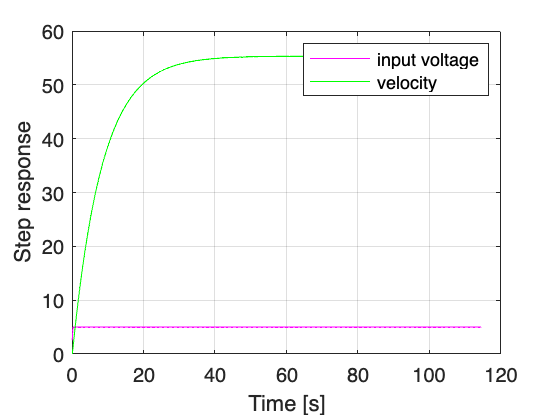

%simulate the estimated model
[GestOutput, time] = lsim(Gest, inputVAve, time, 0);

%create a figure to compare observed velocity and simulated model output
figure;
plot(time, velocity, 'm', time, GestOutput, 'g');
xlabel('Time [s]');
ylabel('Velocity');
legend('Observed Velocity', 'Simulated Model Output');
title('Comparison of Observed Velocity and Simulated Model Output');

## Find Sensor Coefficient

% Assuming you have arrays of velocity and output voltage
% Find the index where the sensor saturates (output voltage = 10)
saturateIndex = find(outputVAve == 10, 1);

h = mean(outputVAve(2:saturateIndex)./outputYAve(2:saturateIndex));

% Display the value of h
disp(['The constant h is: ', num2str(h)]);

The constant h is: 0.76604



disp(velocity(1000));

   55.3500

